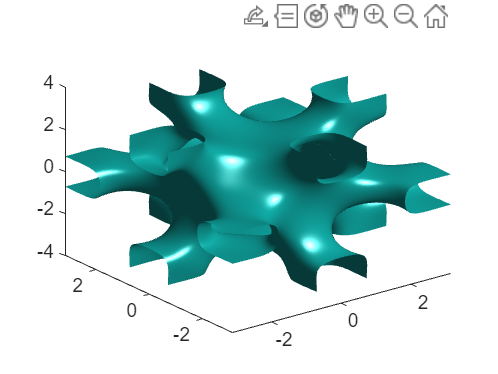

clear;clc;
% x1 = [-0.5:0.01:0.5]*2*pi;
% y1 = [-0.5:0.01:0.5]*2*pi;
% z1 = [-0.5:0.01:0.5]*2*pi;
% t1 = -0.289;
% [X1,Y1,Z1] = meshgrid(x1,y1,z1);
% F1 = cos(X1) + cos(Y1) + cos(Z1)+ t1;
% 
% x2 = [-0.5:0.01:0.5]*2*pi;
% y2 = [-0.5:0.01:0.5]*2*pi;
% z2 = [-0.5:0.01:0.5]*2*pi;
% t2 = -0.0536;
% [X2,Y2,Z2] = meshgrid(x2,y2,z2);
% F2 = cos(X2).*cos(Y2).*cos(Z2) - sin(X2).*sin(Y2).*sin(Z2) + t2;
% 
% x3 = [-0.5:0.01:0.5]*2*pi;
% y3 = [-0.5:0.01:0.5]*2*pi;
% z3 = [-0.5:0.01:0.5]*2*pi;
% t3 = -0.000417;
% [X3,Y3,Z3] = meshgrid(x3,y3,z3);
% F3 = 8*cos(X3).*cos(Y3).*cos(Z3)+cos(2*X3).*cos(2*Y3).*cos(2*Z3)-(cos(2*X3).*cos(2*Y3)+cos(2*Y3).*cos(2*Z3)+cos(2*Z3).*cos(2*X3))+t3;

alpha1 = 0.411;
alpha2 = 0.144;
alpha3 = 0.445;
t1 = -0.120;
t2 = -0.349;
t3 = -0.359;

x = [-0.5:0.01:0.5]*2*pi;
y = [-0.5:0.01:0.5]*2*pi;
z = [-0.5:0.01:0.5]*2*pi;
[X,Y,Z] = meshgrid(x,y,z);

F1 = cos(X) + cos(Y) + cos(Z)+ t1;
F2 = cos(X).*cos(Y).*cos(Z) - sin(X).*sin(Y).*sin(Z) + t2;
F3 = 8*cos(X).*cos(Y).*cos(Z)+cos(2*X).*cos(2*Y).*cos(2*Z)-(cos(2*X).*cos(2*Y)+cos(2*Y).*cos(2*Z)+cos(2*Z).*cos(2*X))+t3;
Fmerge = alpha1*4*F1+alpha2*4*F2+alpha3*F3;



% figure(1)
% isosurface(X1,Y1,Z1,F1,1e-20)
% 
% 
% isosurface(X2,Y2,Z2,F2,1e-20)
% daspect([1 1 1]);

% figure(2)
% isosurface(X3,Y3,Z3,F3,1e-4)

figure(2)
isosurface(X,Y,Z,Fmerge,1e-4)